## 绘制FWGN信道模型

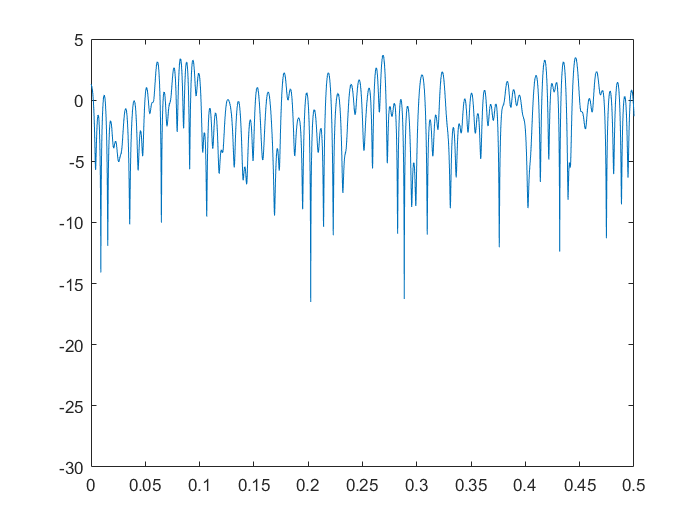

clear,clf,clc
fm = 100;
ts_mu = 50;
scale = 1e-6;
ts = ts_mu*scale;
fs = 1/ts;
Nd = 1e6;
[h,Nfft,Nifft,doppler_coeff] = FWGN_model(fm,fs,Nd);
plot((1:Nd)*ts,10*log10(abs(h)))
axis([0 0.5 -30 5]);

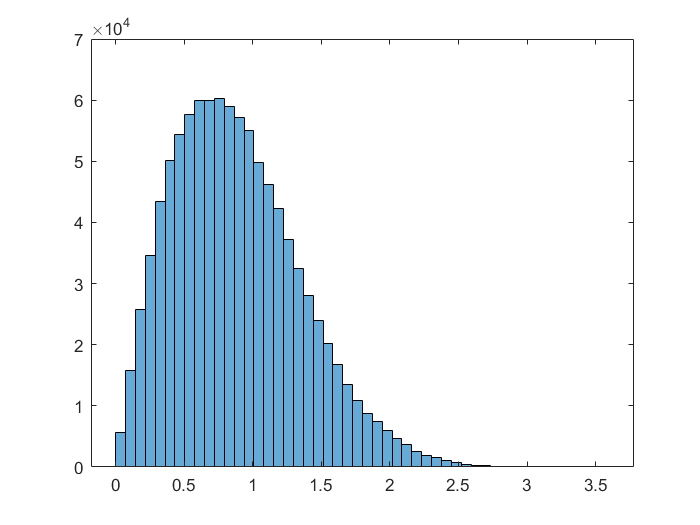

histogram(abs(h),50);

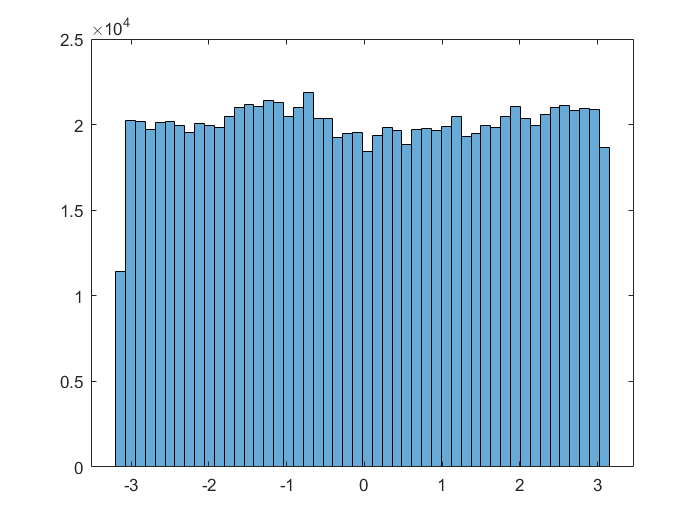

histogram(angle(h),50);